# ECEN5463 | HW2

Collin Thornton

## Problem 1

Must find all values of $r \in \mathbb{R}$ such that the ball of radius $\bar B(0,r) \subset \mathbb{R}^m$ with resepct to $\dot x = f(x), x \in \mathbb{R}^m$ implies $\forall x \in \partial B(0,r), f^T(x)n(x)\leq0$

syms x1 x2 r th

X = [x1;x2];
f = [x1 + x2 - x1*(x1^2+x2^2);
     -2*x1 + x2 - x2*(x1^2 + x2^2)];

Equation of a circle: $x^2 +y^2 =r^2$

Normal vector = $<\cos \left(\theta \right),\sin \left(\theta \right)>$

Convert dynamics to polar coordinates

- 
$$r\dot{\;r} =x_1 \dot{x_1 } +x_2 \dot{\;x_2 }$$


- 
$$r^2 \dot{\;\theta \;} =x_1 \dot{\;x_2 } -x_2 \dot{\;x_1 }$$


n = [cos(th); sin(th)];

rrdot = simplify(x1*f(1)+x2*f(2));
r2the = simplify(x1*f(2)-x2*f(1));

rdot = simplify(subs(rrdot, [x1,x2], [r*cos(th), r*sin(th)])/r);
tdot = simplify(subs(r2the, [x1,x2], [r*cos(th), r*sin(th)])/r^2);
%f_p = [rdot;tdot]

*Note:* Couldn't get the equations for $\dot{\;r}$ and $\dot{\;\theta \;}$ to simplify to an appropriate answer. Simplifying to the following equation:

f_p = collect(simplify(subs(f, [x1,x2], [r*cos(th), r*sin(th)])))

$$f\_p = \left(\begin{array}{c} r\,\left(-\cos\left(\mathrm{th}\right)\,r^{2}+\cos\left(\mathrm{th}\right)+\sin\left(\mathrm{th}\right)\right)\\ -r\,\left(\sin\left(\mathrm{th}\right)\,r^{2}+2\,\cos\left(\mathrm{th}\right)-\sin\left(\mathrm{th}\right)\right) \end{array}\right)$$

G = collect(simplify(transpose(f_p)*n))

$$G = -r\,\left(r^{2}+\frac{\sin\left(2\,\mathrm{th}\right)}{2}-1\right)$$

sol = simplify(solve(G==0,r))

$$sol = \left(\begin{array}{c} 0\\ -\frac{\sqrt{2}\,\sqrt{2-\sin\left(2\,\mathrm{th}\right)}}{2}\\ \frac{\sqrt{2}\,\sqrt{2-\sin\left(2\,\mathrm{th}\right)}}{2} \end{array}\right)$$

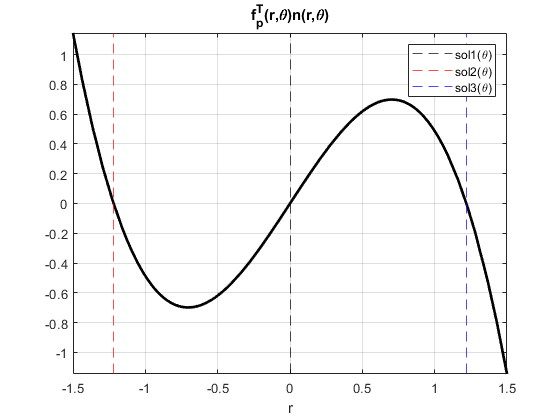

theta =-0.9;
figure()

fplot(subs(G,th,theta), [-1.5,1.5], '-k', "LineWidth", 2)
hold on
xline(double(subs(sol(1),th,theta)), '--k');
xline(double(subs(sol(2),th,theta)), '--r');
xline(double(subs(sol(3),th,theta)), '--b');
legend()
grid on
xlabel("r")
title("f_p^T(r,\theta)n(r,\theta)")
legend("", "sol1(\theta)", "sol2(\theta)", "sol3(\theta)")

Thus, $\bar{\;B} \left(0,r\right)$is positively invariant with respect to $f\left(x\right)=\dot{\;x}$ on the interval $r \geq\frac{\sqrt{2}\sqrt{2-\sin(\theta)}}{2}$

## Problem 2 

### 2-1 Show that the system $\dot{x} =x^2$ admits solutions that blow up to infinity in finite time

One solution is to prove that the function $f\left(t,x\right)$is not Lipschitz continuous with respect to $x$.

- 
$$f\left(t,x\right)=\dot{x} =x^2$$


First step, find the limit of $\frac{d}{\textrm{d}x}f\left(t,x\right)=2x$ as $x\to \pm \infty \;$.

- 
$$\lim_{x\to \infty \;} \frac{\textrm{d}}{\textrm{d}x}f\left(t,x\right)\;=2\left(\infty \;\right)$$


- 
$$\lim_{x\to -\infty \;} \frac{\textrm{d}}{\textrm{d}x}f\left(t,x\right)=2\left(\infty \;\right)\;$$


As $\frac{\textrm{d}}{\textrm{d}x}f\left(t,x\right)$is not bounded as $x\to \pm \infty \;$, $||f\left(t,x\right)-f\left(t,x+1\right)||=\infty \;,\mathrm{as}\;x\to \pm \infty \;$

- **Therefore, **$f\left(t,x\right)$**is not Lipschitz continuous and thus admits solutions that blow up to infinity in finity time.**

This holds as:

- 
$$F\left(t,x\right)=\int_t f\left(t,x\right)\;\mathrm{dt}=\int_t x^2 \;\mathrm{dt}$$


Take the case $t=\left\lbrack 0,1\right\rbrack$, $x=\infty \;$.

-     
$$F\left(1,\infty \right)=\lim_{x\to \infty \;} \int_0^1 x^2 \;\mathrm{dt}\;=\lim_{x\to \infty } \;x^2 =\infty^2 =\infty \;$$


## Problem 3 Prove whether the following functions are continous from $\mathbb{R}$ to $\mathbb{R}$

Continuous functions $f\left(x\right)$ must satisfy the following points to be called piecewise continous:

- $t\to f\left(t,x\right)$contains a finite number of discontinuties at $t\in J$

- 
$$\forall \;t\in J,\lim_{h\to 0^+ } f\left(t+h,x\right)\;\mathrm{and}\;\lim_{h\to 0^- } \;f\left(t+h,x\right)\;\mathrm{exist}\;\mathrm{and}\;\mathrm{are}\;\mathrm{finite}$$


### 3-1 $f\left(x\right)=\max \left(0,x\right)$

syms x

f = x*heaviside(x);
disc = feval(symengine, 'discont', f, x)

$$disc = \left\{0\right\}$$

There is only 1 discontinuous point

limit(f,x,0,'left')

$$ans = 0$$

limit(f,x,0,'right')

$$ans = 0$$

subs(f,x,0)   

$$ans = 0$$

Both limits exist and are equivalent. Therefore $f\left(x\right)=\max \left(0,x\right)$ is **continous**.

### 3-2 $f\left(x\right)=\left\lbrace \begin{array}{ll}
\sin \left(x\right) & x>0\\
0 & x\le 0
\end{array}\right.$

syms x
f = sin(x)*heaviside(x);

disc = feval(symengine, 'discont', f, x)

$$disc = \left\{0\right\}$$

There is only 1 discontinuous point

limit(f,x,0,'left')

$$ans = 0$$

limit(f,x,0,'right')

$$ans = 0$$

subs(f,x,0)

$$ans = 0$$

Both limits exist and are equivalent. Therefore $f\left(x\right)=\left\lbrace \begin{array}{ll}
\sin \left(x\right) & x>0\\
0 & x\le 0
\end{array}\right.$ is **continous**.

### 3-3 $f\left(x\right)=\textrm{sgn}\left(x\right)=\left\lbrace \begin{array}{ll}
1 & x>0\\
-1 & x<0\\
0 & x=0
\end{array}\right.$

syms x

f = piecewise(x<0, -1, x==0, 0, x>0, 1);

disc =  feval(symengine, 'discont', f, x) 

$$disc = \left\{0\right\}$$

There is only one discontinous point

limit(f,x,0,'left')

$$ans = -1$$

limit(f,x,0,'right')

$$ans = 1$$

subs(f,x,0)                        

$$ans = 0$$

Both limits exist, though they are not equivalent. Therefore $f\left(x\right)=\textrm{sgn}\left(x\right)$ is **not continuous**. (Though it is piecewise continuous)

## Problem 4

Controller state variable: x

- 
$$x=\left\lbrack \begin{array}{c}
q\\
\frac{\textrm{d}}{\textrm{d}t}q\\
\int \;\left(\hat{q} -q\right)\;\mathrm{dt}
\end{array}\right\rbrack$$


- 
$$u=\tau \;$$


- 
$$\ddot{q} ={M\left(q\right)}^{-1} \left(\tau -V_m \left(q,\dot{\;q} \right)\dot{\;q} +F_S \left(\dot{\;q} \right)\right)$$


x0 = zeros(6,1);
tspan = linspace(0,50,1000);

P = cell(3,1);
results = cell(3,2);

P{1} = [3.473;0.196;0.242]; % [p1,p2,p3]'

### 4-1 Develop a PID controll assuming motors can product unlimited torque

P{3} = [-1;-1];     % torque bounds
P{2} = [3,   0, 0;     % [kP, kI, kD]
        1.5, 0, 0];
results{1,1} = ode45(@(t,x) closedLoopDynamics(t,x,P), tspan, x0);

P{2} = [3,   0, 2;
        1.5, 0, 1];
results{2,1} = ode45(@(t,x) closedLoopDynamics(t,x,P), tspan, x0);

P{2} = [3,   0.05, 2;
        1.5, 0.05, 1];
results{3,1} = ode45(@(t,x) closedLoopDynamics(t,x,P), tspan, x0);

### 4-2 Limit torque to 60Nm and 20Nm, respectively, and compare output

P{3} = [60; 20];
P{2} = [3,   0, 0;     % [kP, kI, kD]
        1.5, 0, 0];
results{1,2} = ode45(@(t,x) closedLoopDynamics(t,x,P), tspan, x0);

P{2} = [3,   0, 2;
        1.5, 0, 1];
results{2,2} = ode45(@(t,x) closedLoopDynamics(t,x,P), tspan, x0);

P{2} = [3,   0.05, 2;
        1.5, 0.05, 1];
results{3,2} = ode45(@(t,x) closedLoopDynamics(t,x,P), tspan, x0);
figure()

### Plot and discuss

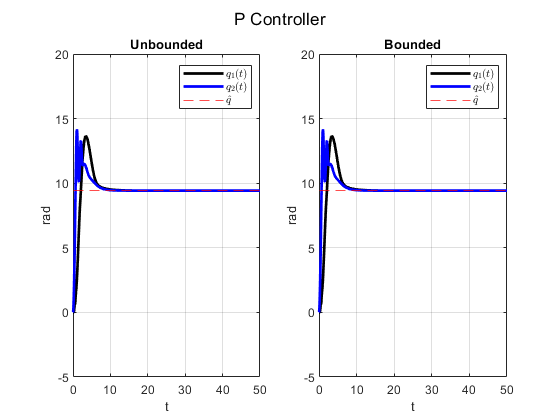

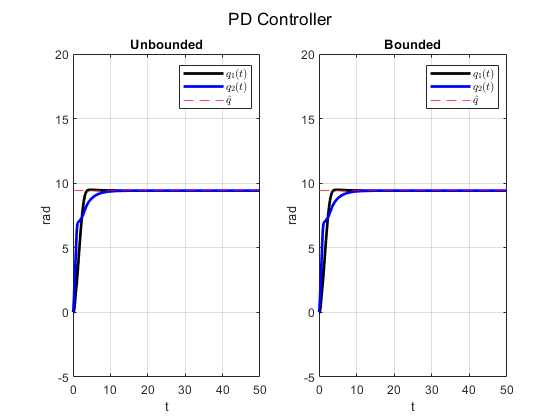

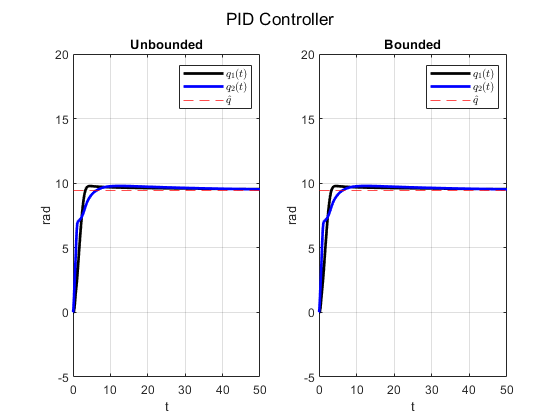

for i = 1:3
    figure()
    for j = 1:2
        if j == 1
            name = "Unbounded";
        else
            name = "Bounded";
        end
        subplot(1,2,j)
        plot(results{i,j}.x, results{i,j}.y(1,:), '-k', "LineWidth", 2)
        hold on
        plot(results{i,j}.x, results{i,j}.y(2,:), '-b', "LineWidth", 2)
        yline(3*pi, '--r');
        
        title(name);
        ylim([-5,20])
        xlim([0,50])
        
        grid on;
        legend("$q_1(t)$", "$q_2(t)$", "$\hat{q}$", "Interpreter", "latex");
        xlabel("t");
        ylabel("rad");
    end
    if i == 1
        sgtitle("P Controller")
    elseif i == 2
        sgtitle("PD Controller")
    else
        sgtitle("PID Controller")
    end
end

Show numerical difference between bounded and unbounded cases

norm(results{1,1}.y - results{1,2}.y)

ans = 0

norm(results{2,1}.y - results{2,2}.y)

ans = 0

norm(results{3,1}.y - results{3,2}.y)

ans = 0

**Unbounded Case:**

Observations about steady state

- All controllers reach steady state within 30 seoncds, converging on $q\left(t\right)={\left\lbrack 3\pi ,3\pi \right\rbrack }^T$ and minimizing $\epsilon \;$.

- The P Controller & PD Controller reach steady state within 30 seconds

- The PID requires an additional 10 seconds to reach steady state

Observations about transient response

- The P controller overshoots by more than 5 radians

- The PD controller as a relatively small overshoot in $q_1 \left(t\right)$of less than $\frac{1}{2}$ radian

- The PID controller overshoots by about 1 radians

Discussion

- The I term is unecessary as there are no steady state disturbances, thus $k_I$ should be set to 0 in order to minimize oscillation

-     $k_I ={\left\lbrack 0\ldotp 05,0\ldotp 05\right\rbrack }^T$ in the PID controller. $k_I$is useful to minimize small error in steady state, though $k_I$ must be small or oscillation will occur

- Increasing the $k_D$ enables a more agressive transient response while reducing overshoot

-     This said, a high $k_D$ will lead to high frequency oscillation in the physical world due to noisy measurements

**Bounded Case:**

Everything is equivalent to the unbounded case as the controller never demands more than 60 Nm and 20 Nm of torque, respectively.

function x_dot = closedLoopDynamics(t, x, P)
    % This function "simulates" the behavior of a two-link robot under the
    % controller given by the 'control' function.
    x_dot = openLoopDynamics(t, x, control(t,x,P), P);
end


function x_dot = openLoopDynamics(t, x, u, P)
    % This function "simulates" the behavior of a two-link robot
    % manipulator using a model in the state space form. 
    %
    % TODO: Use the given equations to compute x_dot using t, x, and u
    p = P{1};
    
    M = [p(1)+2*p(3)*cos(x(2)), p(2)+p(3)*cos(x(2));
         p(2) + p(3)*cos(x(2)), p(2)];
    V = [-p(3)*sin(x(2))*x(4), -p(3)*sin(x(2))*(x(3)+x(4));
         p(3)*sin(x(2))*x(3), 0];
    F = [8.45*tanh(x(3)); 2.35*tanh(x(4))];
    
    ddq = M\(u - V*x(3:4) - F);
    x_dot = [x(3:4);ddq;3*pi-x(1:2)];
end

function u = control(t, x, P)
    % This function calculates the control signal (a vector containing the
    % torque commands for the two joints of the two-link robot) as a
    % function of time and state
    % Use the given equations to compute u using from t and x here   
    K = P{2};
    bounds = P{3};
    
    e = [3*pi;3*pi] - x(1:2);
    de = -x(3:4);
    
    
    s = [e,x(5:6),de];
    u = zeros(size(bounds));
    
    for i = 1:length(bounds)
        u(i) = K(i,:)*s(i,:)';
        
        if bounds(i) > 0
            u(i) = min(u(i), bounds(i));
        end
    end
end